%% RPTU Paritásellenőrző Mátrix ($H$) beolvasása és Szimulációja
% Ez a szkript bemutatja, hogyan dolgozzuk fel az RPTU adatbázisból származó
% kicsomagolt (.txt) AList formátumú fájlokat, és hogyan szimuláljuk le rajtuk a csatornakódolást.

%%@misc{channelcodes,
%author = "Helmling, Michael and Scholl, Stefan and Gensheimer, Florian and Dietz, Tobias and Kraft, Kira and Griebel, Oliver and Ruzika, Stefan and Wehn, Norbert",
%title = "{D}atabase of {C}hannel {C}odes and {ML} {S}imulation {R}esults",
%howpublished = "\url{www.rptu.de/channel-codes}",
%year = "2025"
%}

clear; clc; close all;

%% 1. Fájlnév megadása
% Ez a .txt fájl egy hagyományos (sűrű) mátrixot tartalmaz 0-kkal és 1-esekkel.
hFilename = 'LTE_TC_N132_K40.txt';

%% 2. A fájl beolvasása és Sparse Mátrix generálása (A parser)
fprintf('--- Fájl feldolgozása ---\n');

--- Fájl feldolgozása ---


% A beolvasás sokkal egyszerűbb, mivel sűrű mátrix formátumról van szó:
H_dense = readmatrix(hFilename);

% A MATLAB LDPC dekódolója ritka (sparse) LOGIKAI (logical) mátrixot vár,
% ezért átkonvertáljuk a számokat logikai értékekké a ritkítás előtt:
H_sparse = sparse(logical(H_dense));

% Méretek meghatározása
[M, N] = size(H_sparse); 
K = N - M; % Hasznos bitek száma (közelítés, ha H teljes rangú)
kodarany = K / N;

fprintf('Mátrix mérete: %d oszlop (N), %d sor (M)\n', N, M);

Mátrix mérete: 132 oszlop (N), 92 sor (M)


fprintf('Kódarány: ~%.2f\n\n', kodarany);

Kódarány: ~0.30




% Opcionális: a sparse mátrix mentése MATLAB natív formátumba a jövőre nézve
save('rptu_matrix.mat', 'H_sparse'); 

%% 3. Kommunikációs Szimuláció beállítása
% A szimuláció során valódi, véletlenszerűen generált biteket küldünk át, 
% melyeket az LDPC kódolóval kódolunk, majd QPSK-val modulálunk.

snr_dB_array = 0:2:8; % Szimulált Jel-Zaj viszonyok (SNR) decibelben
max_hibas_blokk = 50; % Hány hibás keretig fusson egy SNR ponton
max_keret = 10000;    % Maximum hány keretet küldjünk
ber_results = zeros(size(snr_dB_array));

% Dekódoló beállítása: A MATLAB beépített üzenettovábbító (Belief Propagation) 
% LDPC dekódoló konfigurációját használjuk a mátrixunkhoz az új ldpcDecode függvénnyel.
cfgLDPCDec = ldpcDecoderConfig(H_sparse);

% ÚJ RÉSZ: Kódoló beállítása a valódi véletlen adatokhoz
% A H mátrixból a MATLAB megpróbálja előállítani a kódoláshoz szükséges G mátrixot.
try
    cfgLDPCEnc = ldpcEncoderConfig(H_sparse);
catch
    error('A megadott H mátrixból nem lehet kódolót generálni. A valós adatos szimulációhoz teljes rangú mátrix kell!');
end

max_iter = 20; % Maximum iterációk száma a dekódoláshoz

fprintf('--- Szimuláció indítása (Valódi adatokkal és QPSK modulációval) ---\n');

--- Szimuláció indítása (Valódi adatokkal és QPSK modulációval) ---


for snr_idx = 1:length(snr_dB_array)
    snr = snr_dB_array(snr_idx);
    hiba_szam = 0;
    bit_szam = 0;
    hibas_blokkok = 0;
    
    for keret = 1:max_keret
        % 1. Valódi véletlen adat generálása (K bitnyi 0 és 1)
        data = randi([0 1], K, 1);
        
        % 2. Kódolás a paritásmátrix konfigurációja alapján (a convenc() alternatívája)
        codedData = ldpcEncode(data, cfgLDPCEnc);
        
        % 3. QPSK Moduláció előkészítése
        % A biteket 2-esével párosítjuk (N=132 páros, így pont N/2 = 66 szimbólum lesz)
        cD1 = reshape(codedData, [2, N/2])';
        input1 = bi2de(cD1, "left-msb");
        
        % QPSK Moduláció (4 állapot, pi/4 elforgatás)
        tx_szimbolumok = pskmod(input1, 4, pi/4);
        
        % 4. Csatorna zaj (AWGN)
        rx_szimbolumok = awgn(tx_szimbolumok, snr, 'measured');
        
        % 5. Demoduláció (Soft Decision LLR)
        zaj_teljesitmeny = 10^(-snr/10); 
        rx_llr = pskdemod(rx_szimbolumok, 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', zaj_teljesitmeny);
        
        % Biztosítjuk, hogy Nx1-es oszlopvektor legyen az ldpcDecode-hoz
        rx_llr = rx_llr(:);
        
        % 6. Dekódolás a mátrix (H) alapján (ez helyettesíti a vitdec-et)
        rx_bitek = ldpcDecode(rx_llr, cfgLDPCDec, max_iter);
        
        % 7. Hibaszámítás (Eredeti vs. Dekódolt)
        hibak_a_keretben = biterr(data, rx_bitek);
        
        hiba_szam = hiba_szam + hibak_a_keretben;
        bit_szam = bit_szam + K; % A dekódoló K bitet ad vissza
        
        if hibak_a_keretben > 0
            hibas_blokkok = hibas_blokkok + 1;
        end
        
        if hibas_blokkok >= max_hibas_blokk
            break; % Elég statisztika gyűlt össze ehhez az SNR-hez
        end
    end
    
    ber_results(snr_idx) = hiba_szam / bit_szam;
    fprintf('SNR = %d dB | BER = %e | Értékelt keretek: %d\n', snr, ber_results(snr_idx), keret);
end

SNR = 0 dB | BER = 8.928571e-02 | Értékelt keretek: 98
SNR = 2 dB | BER = 3.657895e-02 | Értékelt keretek: 190
SNR = 4 dB | BER = 1.753247e-02 | Értékelt keretek: 385
SNR = 6 dB | BER = 9.379085e-03 | Értékelt keretek: 765
SNR = 8 dB | BER = 3.965613e-03 | Értékelt keretek: 1803


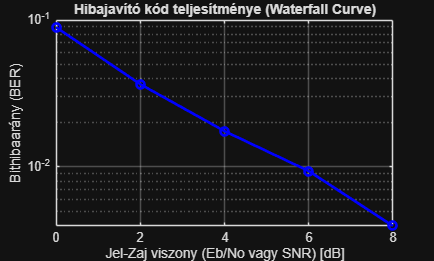


%% 4. Eredmények kirajzolása (Vízesés görbe / Waterfall curve)
figure('Name', 'RPTU Kód Teljesítménye', 'NumberTitle', 'off');
semilogy(snr_dB_array, ber_results, 'b-o', 'LineWidth', 2);
grid on;
xlabel('Jel-Zaj viszony (Eb/No vagy SNR) [dB]');
ylabel('Bithibaarány (BER)');
title('Hibajavító kód teljesítménye (Waterfall Curve)');